# FTFS and FTBS Schemes for Scalar Advection Equations

We are solving the following advection equation with periodic boundary condition.


$$u_t+u_x=0, t\geq 0, x\in [0, 2\pi],\\
u(x,0)=u_0(x),\\
u(0,t)=u(2\pi, t), \forall t\geq 0.$$


with the FTFS and FTBS schemes.

## FTBS scheme

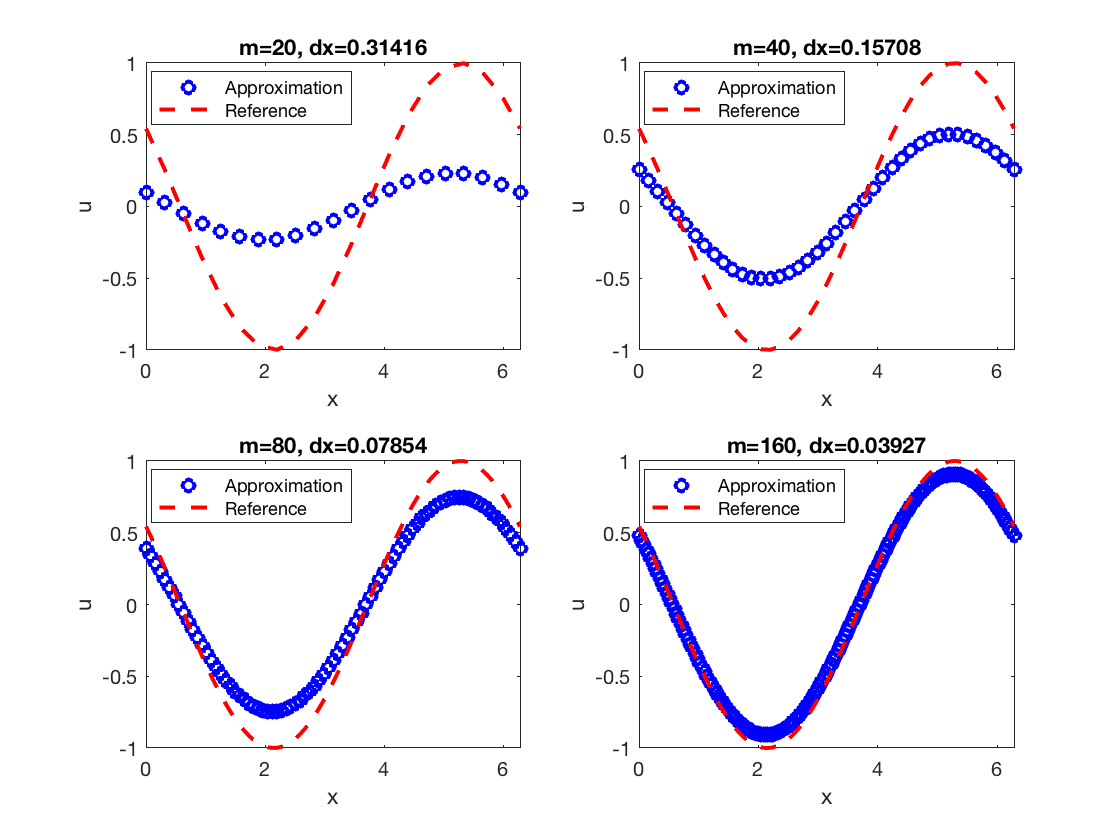

%spatial domain [0, 2\pi]
a=0;
b=2*pi;

%initial condition (periodic function)
u0=@(x) sin(x);

%time step size
dt=0.05;
n_t=500;
T=n_t*dt;

figure;
%A uniform grid with 101 points are placed over the spatial domain.
for j=1:4
    m=2^j*10;
    %Generate the grid
    x=linspace(a,b,m+1);
    
    %grid/mesh size
    dx=(b-a)/m;
    
    
    u=u0(x);
    for i=1:n_t
       u(2:m+1)=u(2:m+1)-dt/dx*(u(2:m+1)-u(1:m));
       u(1)=u(end);
    end
    
    u_exact=u0(x-T);
    
    subplot(2,2,j)
    plot(x, u, 'bo', 'LineWidth', 2);
    hold on
    plot(x, u_exact, 'r--', 'LineWidth', 2);
    hold off
    xlabel('x');
    ylabel('u');
    legend('Approximation', 'Reference', 'Location', 'best');
    title(['m=', num2str(m), ', dx=', num2str(dx)])
end

## FTFS scheme

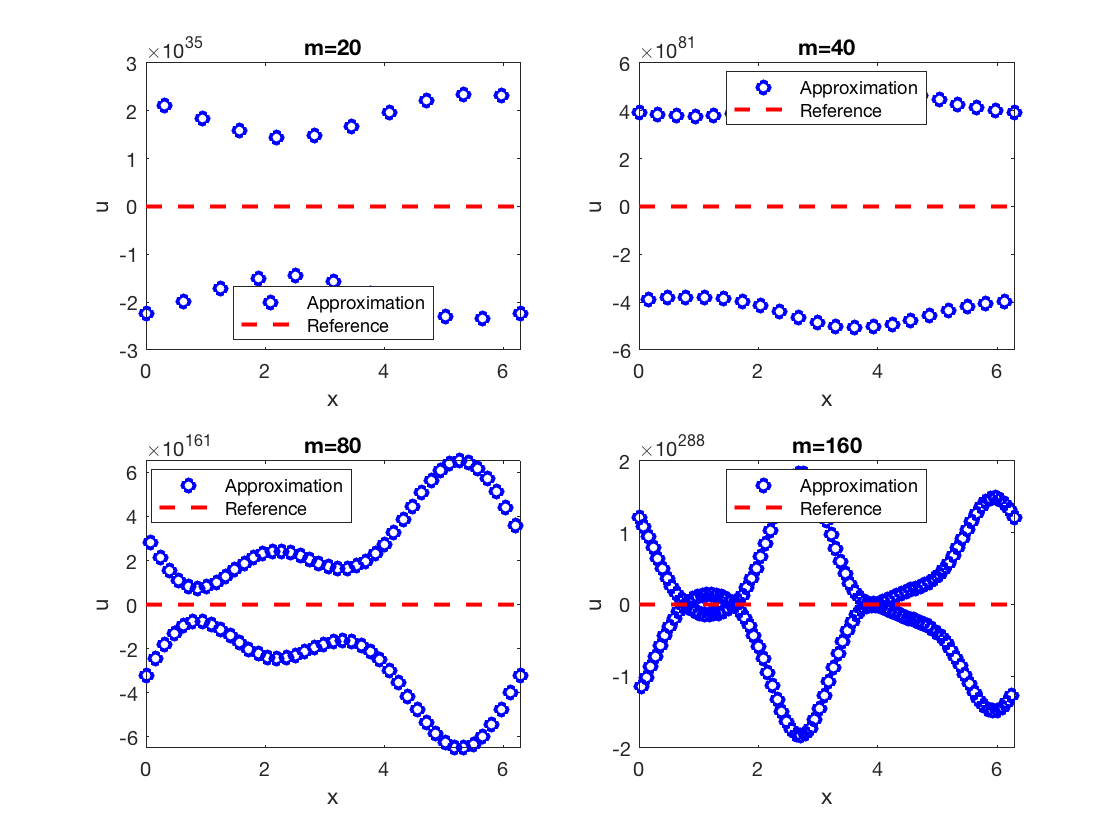

%spatial domain [0, 2\pi]
a=0;
b=2*pi;

%initial condition (periodic function)
u0=@(x) sin(x);

%time step size
dt=0.02;
n_t=1000;
T=n_t*dt;

%A uniform grid with 101 points are placed over the spatial domain.
for j=1:4
    m=10*2^j;
    
    %Generate the grid
    x=linspace(a,b,m+1);
    
    %grid/mesh size
    dx=(b-a)/m;
    
    u=u0(x);
    
    for i=1:n_t
      u(1:m)=u(1:m)-dt/dx*(u(2:m+1)-u(1:m));
      u(m+1)=u(1);   
    end
    u_exact=u0(x-T);
    
    subplot(2,2,j)
    plot(x, u, 'bo', 'LineWidth', 2);
    hold on
    plot(x, u_exact, 'r--', 'LineWidth', 2);
    hold off
    xlabel('x');
    ylabel('u');
    legend('Approximation', 'Reference', 'Location', 'best');
    title(['m=', num2str(m)])
end

## Order of Accuracy of the FTBS scheme in different norms

T=1;
lambda=0.6;
n_refine=8;
err_l1=zeros(n_refine,1);
err_l2=err_l1;
err_l2dx=err_l1;
err_inf=err_l1;

order=@(e) log(e(1:end-1)./e(2:end))./log(2);

%A uniform grid with 101 points are placed over the spatial domain.
for j=1:n_refine
    m=2^j*10;
    %Generate the grid
    x=linspace(a,b,m+1);
    
    %grid/mesh size
    dx=(b-a)/m;
    dt=lambda*dx;
    n_t=floor(T/dt);
    
    u=u0(x);
    for i=1:n_t
       u(2:m+1)=u(2:m+1)-dt/dx*(u(2:m+1)-u(1:m));
       u(1)=u(end);
    end
    
    %after the n_t steps, we may still have T-n_t*dt to arrive at the final time T.
    dt=T-n_t*dt;
    u(2:m+1)=u(2:m+1)-dt/dx*(u(2:m+1)-u(1:m));
    u(1)=u(end);
    
    u_exact=u0(x-T);
    
    err_l1(j)=norm(u-u_exact, 1);
    err_l2dx(j)=norm(u-u_exact, 2)*sqrt(dx);
    err_l2(j)=norm(u-u_exact, 2);
    err_inf(j)=norm(u-u_exact, 'inf');
end

format short e
disp('Numerical errors and orders in the l1 norm:')

Numerical errors and orders in the l1 norm:


disp([err_l1, [0;order(err_l1)]]);

   8.7523e-01            0
   8.4162e-01   5.6493e-02
   8.1687e-01   4.3060e-02
   8.1051e-01   1.1287e-02
   8.0320e-01   1.3071e-02
   8.0214e-01   1.9015e-03
   8.0131e-01   1.4813e-03
   8.0032e-01   1.7949e-03



disp('Numerical errors and orders in the l_inf norm:')

Numerical errors and orders in the l_inf norm:


disp([err_inf, [0;order(err_inf)]])

   6.4559e-02            0
   3.1941e-02   1.0152e+00
   1.5772e-02   1.0181e+00
   7.8906e-03   9.9912e-01
   3.9265e-03   1.0069e+00
   1.9647e-03   9.9895e-01
   9.8234e-04   1.0000e+00
   4.9082e-04   1.0010e+00



disp('Numerical errors and orders in the l_{2,dx} norm:');

Numerical errors and orders in the l_{2,dx} norm:


disp([err_l2dx, [0; order(err_l2dx)]])

   1.1848e-01            0
   5.7667e-02   1.0389e+00
   2.8209e-02   1.0316e+00
   1.4049e-02   1.0057e+00
   6.9749e-03   1.0102e+00
   3.4862e-03   1.0005e+00
   1.7421e-03   1.0008e+00
   8.7019e-04   1.0014e+00



disp('Numerical errors and orders in the l2 norm:')

Numerical errors and orders in the l2 norm:


disp([err_l2, [0; order(err_l2)]])

   2.1139e-01            0
   1.4550e-01   5.3886e-01
   1.0066e-01   5.3162e-01
   7.0895e-02   5.0566e-01
   4.9776e-02   5.1022e-01
   3.5184e-02   5.0054e-01
   2.4865e-02   5.0079e-01
   1.7565e-02   5.0145e-01

